clearvars;
% create the computational grid
xSize = 0.7;        % height of grid in meters
ySize = 0.3;        % length of grid in meters
Nx = 128;           % number of grid points in the x (row) direction
Ny = 64;            % number of grid points in the y (column) direction
dx = xSize/Nx;    	% grid point spacing in the x direction [m]
dy = ySize/Ny;      % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);
% define sound speed in the two layers
c1 = 1500;          % water
%c2 = 1600;         % sediment
c2 = 5100;          % aluminium
%c2 = 3700;          %concrete
% define the properties of the propagation medium
medium.sound_speed = c1 * ones(Nx, Ny);     % [m/s]
medium.sound_speed(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3) = c2;
%medium.sound_speed(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = c2;
medium.density = 1000 * ones(Nx, Ny);       % [kg/m^3]
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 2700; %aluminium
medium.density(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3) = 2700;
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 2300; %concrete
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 1500;  % sediment
medium.alpha_coeff = 0.75;                  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;

% create the time array
kgrid.makeTime(medium.sound_speed);
% I had to increase the number of time steps Nt because the simulation was
% ending too early to view the whole backscatter plot. I used the
% kgrid.makeTime() method to see what the algorithm had used, then manually
% set kgrid.dt to be the same and kgrid.Nt to be slightly larger until the
% simulation ran for an appropriate amount of time - for sediment, not Al
kgrid.Nt

ans = 1842

kgrid.dt

ans = 2.7574e-07

Running k-Wave simulation...
  start time: 22-Mar-2023 12:14:04
  reference sound speed: 5100m/s
  dt: 275.7353ns, t_end: 551.1949us, time steps: 2000
  input grid size: 128 by 64 grid points (700 by 300mm)
  maximum supported frequency: 137.1429kHz by 160kHz
  expanding computational grid...
  computational grid size: 168 by 104 grid points
           Use dimension sizes with lower prime factors to improve speed


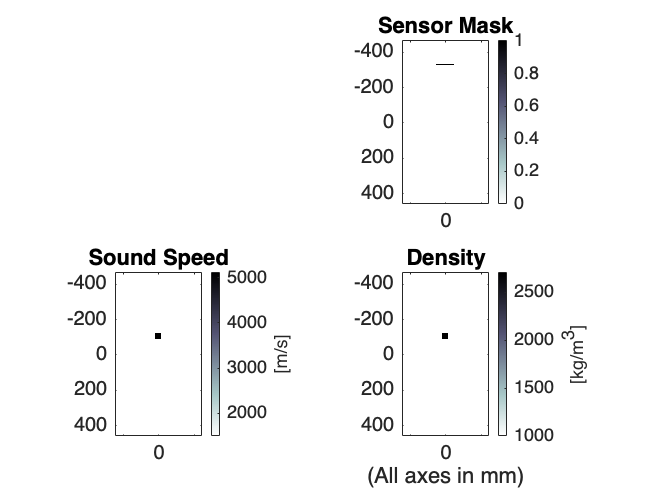

  precomputation completed in 0.86627s
  starting time loop...
  estimated simulation time 48.3481s...


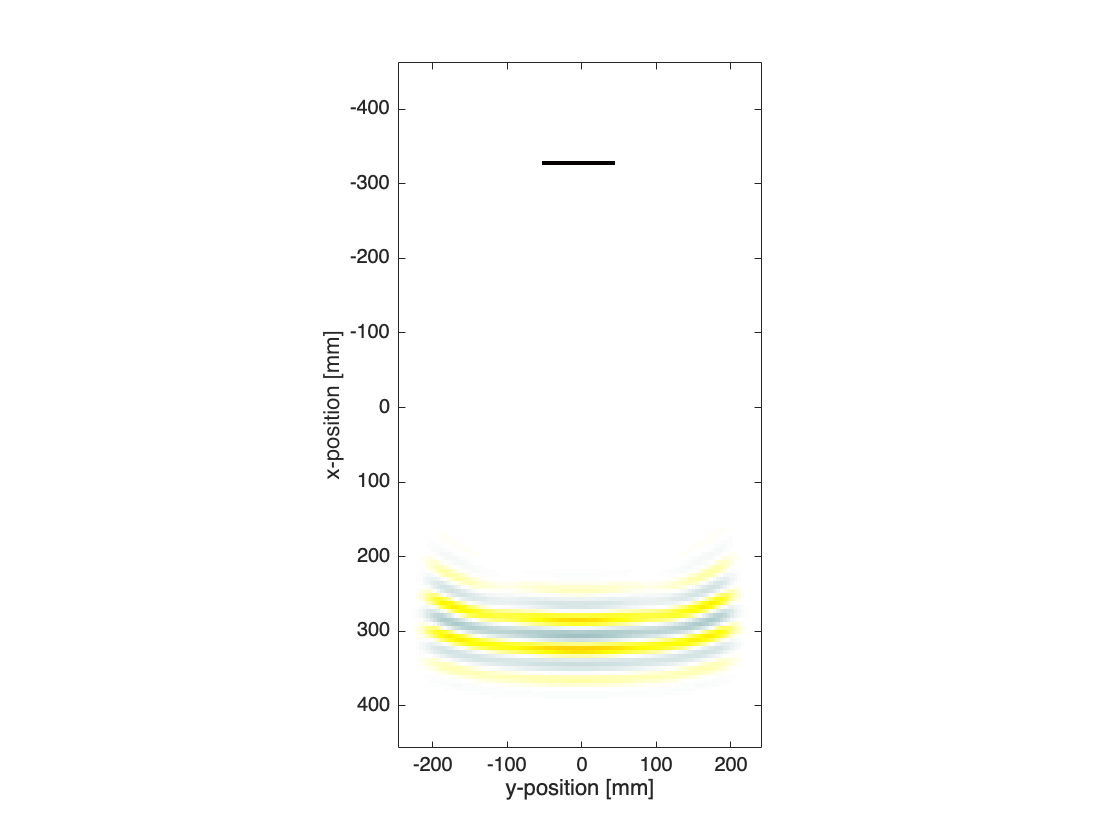

  simulation completed in 21.5718s
  total computation time 22.6524s


kgrid.Nt = 2000;
%kgrid.dt = 2.7574e-7;
% define a source mask for a linear element transducer with an odd number
% of elements

num_elements = 21;
source.p_mask = zeros(Nx, Ny);
x_offset = 5;
y_offset = 20;
start_index = Ny/2 - round(num_elements/2) + 1;
source.p_mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% define the properties of the tone burst
%sampling_freq = 1/kgrid.dt;     % [Hz]
sampling_freq = 20e6;
steering_angle = 0;            % [deg]
element_spacing = dx;           % [m]
tone_burst_freq = 200e3;  %(Hz) frequency of source pulse
tone_burst_cycles = 5;

% create an element index relative to the centre element of the transducer
element_index = -(num_elements - 1)/2:(num_elements - 1)/2;

% use geometric beam forming to calculate the tone burst offsets for each
% transducer element based on the element index
tone_burst_offset = 200 + element_spacing * element_index * ...
    sin(steering_angle * pi/180) / (c1 * kgrid.dt);

% create the tone burst signals
signal = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
    'SignalOffset', tone_burst_offset, 'Envelope', 'Gaussian');
signal = gaussianFilter(signal, sampling_freq, tone_burst_freq, 1000);
source.p = signal;
%source.p = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
%    'SignalOffset', tone_burst_offset, 'Envelope', 'Gaussian');
%source.p = smooth(source.p, true)
% assign the input options
input_args = {'DisplayMask', source.p_mask, 'PMLInside', false, 'PlotLayout', true};

%define sensor mask
sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});

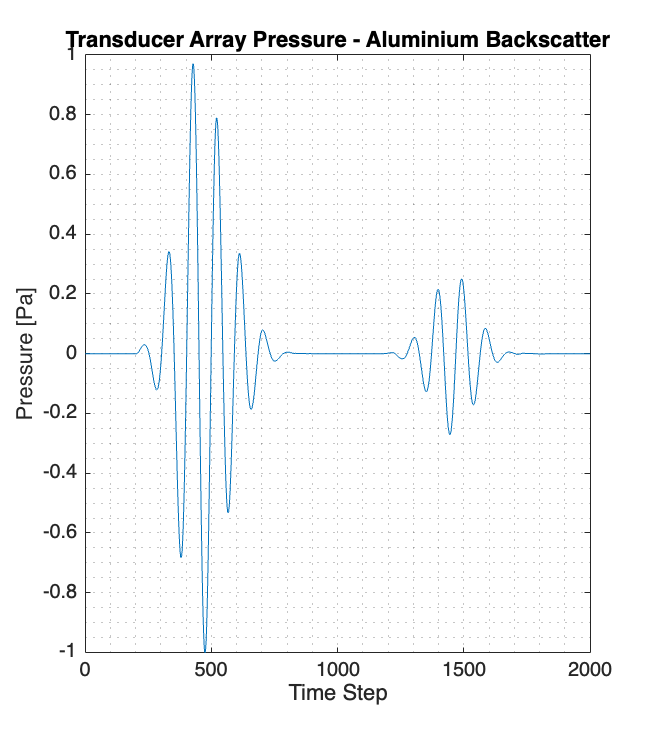

ans = 1.0e-03 *

         0    0.0003    0.0006    0.0008    0.0011    0.0014    0.0017    0.0019    0.0022    0.0025    0.0028    0.0030    0.0033    0.0036    0.0039    0.0041    0.0044    0.0047    0.0050    0.0052    0.0055    0.0058    0.0061    0.0063    0.0066    0.0069    0.0072    0.0074    0.0077    0.0080    0.0083    0.0085    0.0088    0.0091    0.0094    0.0097    0.0099    0.0102    0.0105    0.0108    0.0110    0.0113    0.0116    0.0119    0.0121    0.0124    0.0127    0.0130    0.0132    0.0135



%plot pressure data at middle element
mid_element = round(num_elements/2);
figure;
plot(sensor_data(mid_element, :));
xlabel('Time Step');
ylabel('Pressure [Pa]');
title("Transducer Array Pressure - Aluminium Backscatter")
scaleFig(1, 1.5);
grid minor;